## Modulating Signal 

- What signal to use

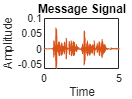

%% Read the audio signal [Modulating Signal]
[Message, Fs] = audioread('epic_voice.wav');


%Message Signal Info
Message_Signal = Message';
N = length(Message_Signal);

time = N/Fs;

%sound(Message, fs);

t = (0:1/Fs:time-1/Fs);

%% Plot Audio Signal
figure(1); plot(t,Message_Signal);
shg;
xlabel ('Time');
ylabel('Amplitude');
title('Message Signal');

## Modulate the Signal 

- Modulation Index = 1

- Carrier Info: Fc = 

%Modulation Index
A = 1;


Error using  / 
Matrix dimensions must agree.

% Carrier Info
Fc = 1135000
Carrier_Signal = (A*cos(2*pi*Fc*t))

%Modulating the Signal

Modulated_Signal = Message_Signal.*Carrier_Signal;

figure(2); plot(t,Modulated_Signal);
shg;
xlabel ('Time');
ylabel('Amplitude');
title('Modulated Signal');





## Amplify the Signal

- Voltage Gain = 0.5

Amplified1 = 5*Modulated_Signal;

## Add Noise

- Add White Gaussian Noise (S/N = 

Signal_With_Noise = awgn(Amplified1,25);

ans = 	1.0e+04 *

       Inf    4.8000    2.4000    1.6000    1.2000    0.9600    0.8000    0.6857    0.6000    0.5333    0.4800    0.4364    0.4000    0.3692    0.3429    0.3200    0.3000    0.2824    0.2667    0.2526    0.2400    0.2286    0.2182    0.2087    0.2000    0.1920    0.1846    0.1778    0.1714    0.1655    0.1600    0.1548    0.1500    0.1455    0.1412    0.1371    0.1333    0.1297    0.1263    0.1231    0.1200    0.1171    0.1143    0.1116    0.1091    0.1067    0.1043    0.1021    0.1000    0.0980


sound(gaussiannoise,Fs)
%%noise
%for graphing:
%minLength = min(length(Message), length(vc))
%voice_message_signal = Message(1:minLength)
%vc = vc(1:minLength)
%gaussiannoise=awgn(Message,53)
%figure;
%plot(t,gaussiannoise)
%title('Gaussian Noise')

## Demodulate the Signal

- Demodulating Circuit = 

%Initialization
Fs = 22050;

Error using demod (line 90)
The carrier frequency must be less than half the sampling frequency.

numSamples = 10000;
DownsampleFactor = 15;
frameSize = 10*DownsampleFactor; 
%Sine Wave System Object
sine = dsp.SineWave([0.4 1],[10 200], ...
    'SamplesPerFrame',frameSize, ...
    'SampleRate',Fs);
%Lowpass FIR FIlter
lp1 = dsp.FIRFilter('Numerator',firpm(20,[0 0.03 0.1 1],[1 1 0 0]));
%3 Digital Filter System Objects
N = 60; % Filter order
hilbertTransformer = dsp.FIRFilter( ...
        'Numerator',firpm(N,[0.01 .95],[1 1],'hilbert'));
delay = dsp.Delay('Length',N/2);
lp2 = dsp.FIRFilter('Numerator',firpm(20,[0 0.03 0.1 1],[1 1 0 0]));
%Two Time Scope System Objects
scope1 = timescope( ...
  'Name','Envelope detection using Amplitude Modulation', ...
  'SampleRate',[Fs,Fs/DownsampleFactor], ...
  'TimeDisplayOffset',[(N/2+frameSize)/Fs,0], ...
  'TimeSpanSource','property', ...
  'TimeSpan',0.45, ...
  'YLimits',[-2.5 2.5], ...
  'Position', [100 200 560 500]);
pos = scope1.Position;

scope2 = timescope( ...
  'Name','Envelope detection using Hilbert Transform', ...
  'Position',[pos(1) + pos(3), pos(2:4)], ...
  'SampleRate',[Fs,Fs/DownsampleFactor], ...
  'TimeDisplayOffset',[(N/2+frameSize)/Fs,0], ...
  'TimeSpanSource','Property', ...
  'TimeSpan',0.45, ...
  'YLimits',[-2.5 2.5]);

%Steam Processing Loop
for i = 1:numSamples/frameSize
    sig = sine();
    sig = (1 + sig(:,1)) .* sig(:, 2);      % Amplitude modulation

    % Envelope detector by squaring the signal and lowpass filtering
    sigsq = 2 * sig .* sig;
    sigenv1 = sqrt(lp1(downsample(sigsq,DownsampleFactor)));

    % Envelope detector using the Hilbert transform in the time domain
    sige = abs(complex(0, hilbertTransformer(sig)) + delay(sig));
    sigenv2 = lp2(downsample(sige,DownsampleFactor));

    % Plot the signals and envelopes
    scope1(sig,sigenv1);
    scope2(sig,sigenv2);
end
release(scope1);
release(scope2);

## Amplify the Signal

- Voltage Gain = 

## Recover the Received Signal

- Show Graph & Play Audio